LTI System Description

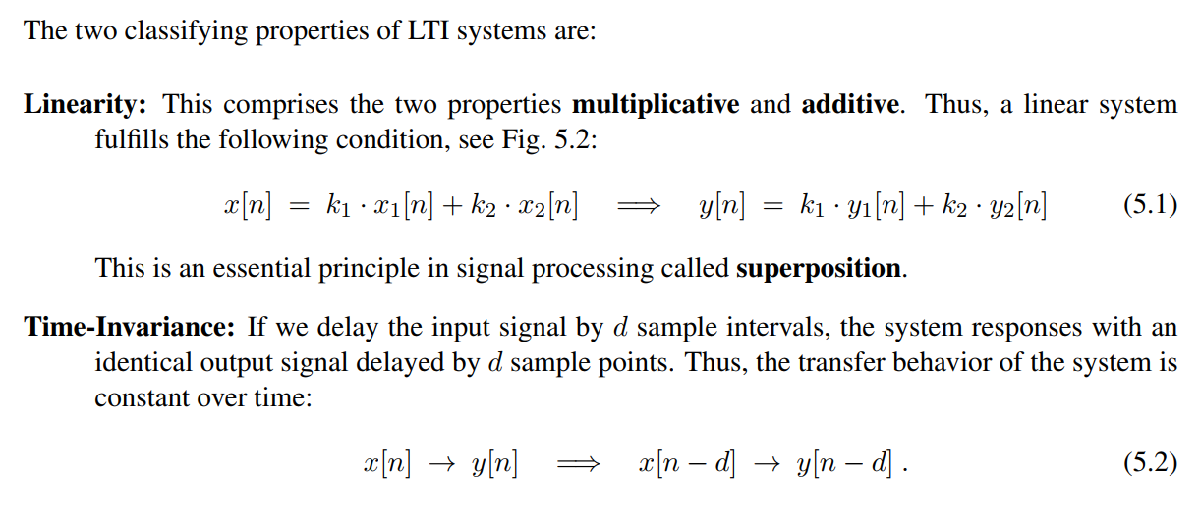

## **Impulse Response Def:** Output of system if input is Unitimpulse

Input Signal:

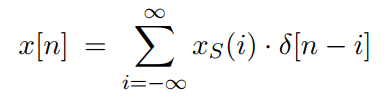

x_s=[1 2 3 2 1 2 3 2];
rho=[1];
x_n=conv(x_s,rho); % Our Imput Signal is a series of weighted unit impulses
figure;
subplot(3,1,1)

Output of LTI System:

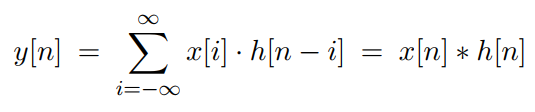 

The Output of an LTI System is the Convolution of the Input with the Impulseresponse.

Since the Input Signal is a series of weightet Unitimpulses, the System reacts to each of these

with a convolution .  

**Meaning in Order to get the Output, we need to find the Impulseresponse. **

**??? can i rewrite this as h[n]*x[n-i] ???**

x=ones(1,8);
h=[1 0 1 0];
%y_1=myConv(x,h)
y_2=conv(x,h)

y_2 =      1     1     2     2     2     2     2     2     1     1     0


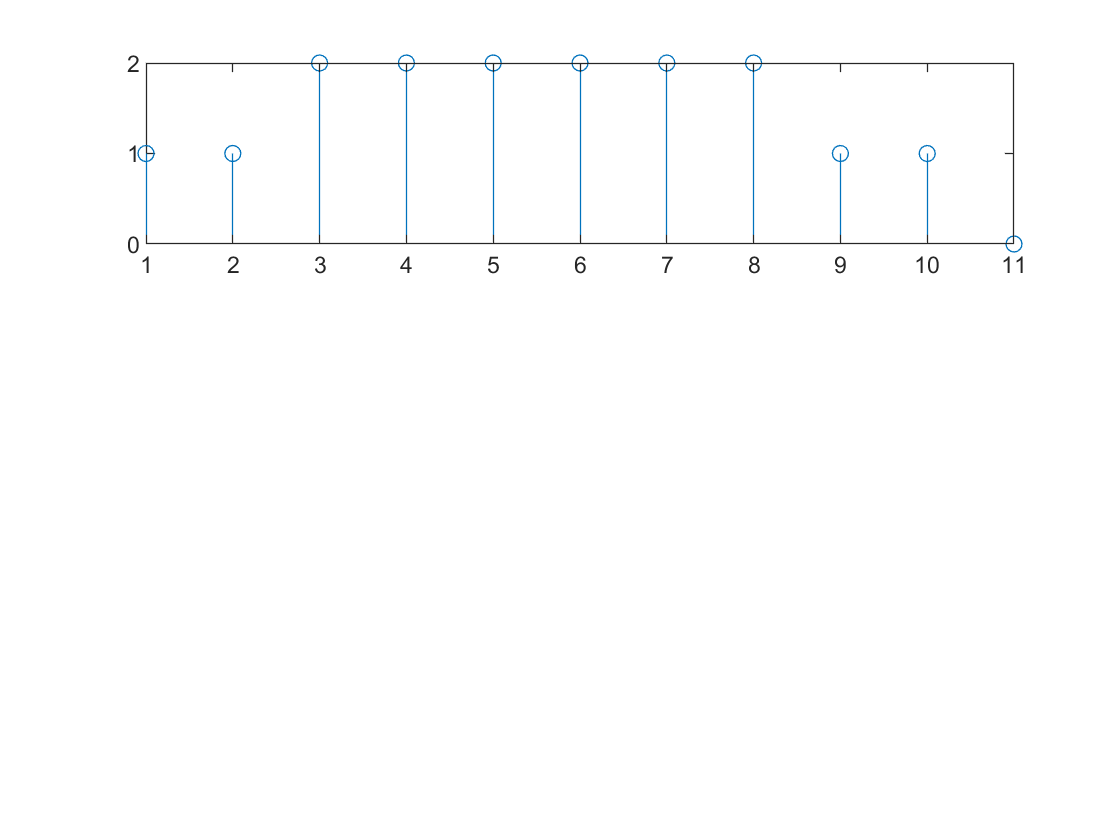


figure(1);
%subplot(2,1,1)
%stem(y_1)
%subplot(2,1,2)
stem(y_2)


%bla

## Difference Equation:

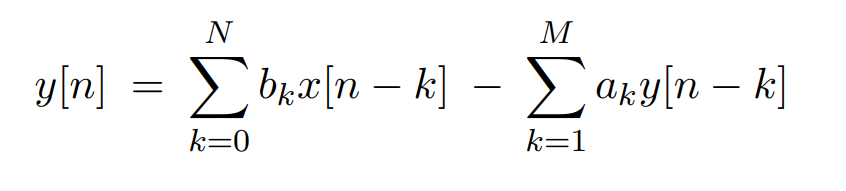

- (N,M) is Order of System

- M bigger 1= system is recursive = past inputs have an influence=feedback loops

- b_k and a_k influece system behaviou

- b_k is also an array with values, so its also a convolution, so we shift the whole signal of x one to the right, multiply it with b_k and add the result this is your y

Let's make a=0 so we only have the first term. This looks pretty much like a convolution (even though i am not sure since b_k could also be just one number)

**!!! For FIR Systems, h[n] corresponds to b_k !!!**

%bla

## **Signal Flow Diagram**

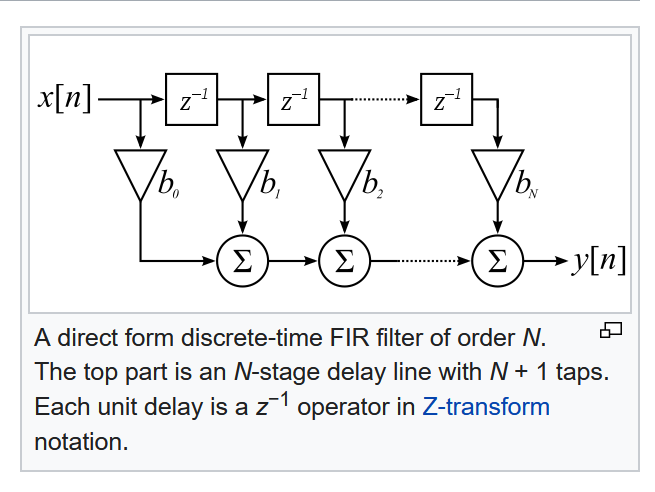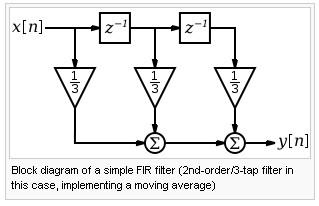

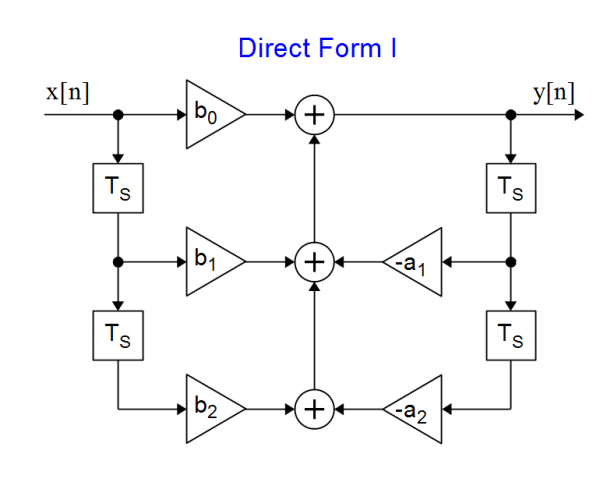

Obserations: 

- a delay of one corresponds to one sample 

- with a=0 does the direct form correspond to the direct form 1 or to another one?

## Frequency Domain - Transferfunction

- How to get Y(z):

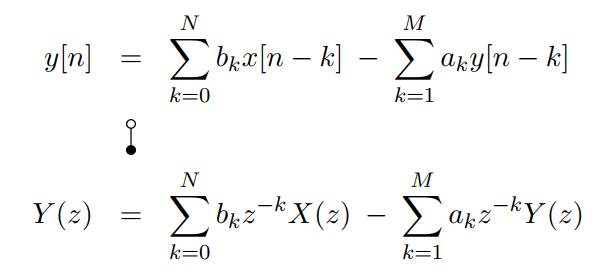

- Definition of H(Z):

(can i replace z^-1 with x[n-1]

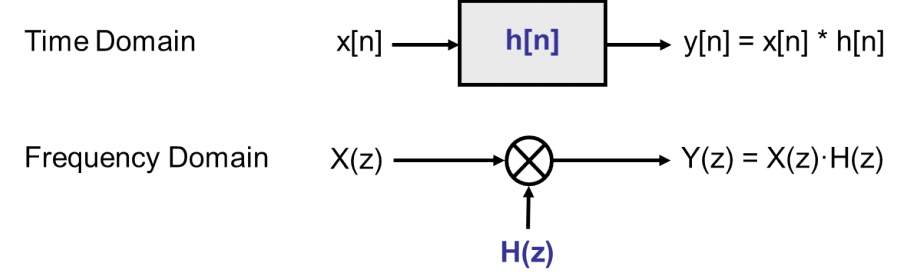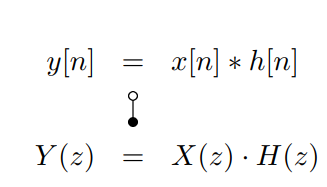

## Pole Zero - Plot

- The Transferfunction gives us the coefficients of the difference equation

- The Difference Equation tells us how to implement the system

- The Polezeroplot tells us the behaviour of the system

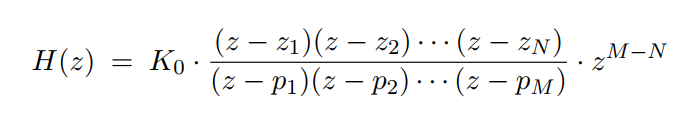

- z_1...z_N are the zeroes of the system

- p_1...p_N are the poles of the system

- K_0 is the Gain of the system

- if N>M then N-M additional Poles at z=0

- N<M

- Causal System is only Stable if all poles are located within the Unitcircle

system=[0 1] % should just delay a signal

system =      0     1


Numerator=[0 0 1]

Numerator =      0     0     1


Denumerator=[1]

Denumerator = 1

inputSignal=[0 1 0] %so it should be delayed by one - [0 0 0 1 0 0 ...]

inputSignal =      0     1     0


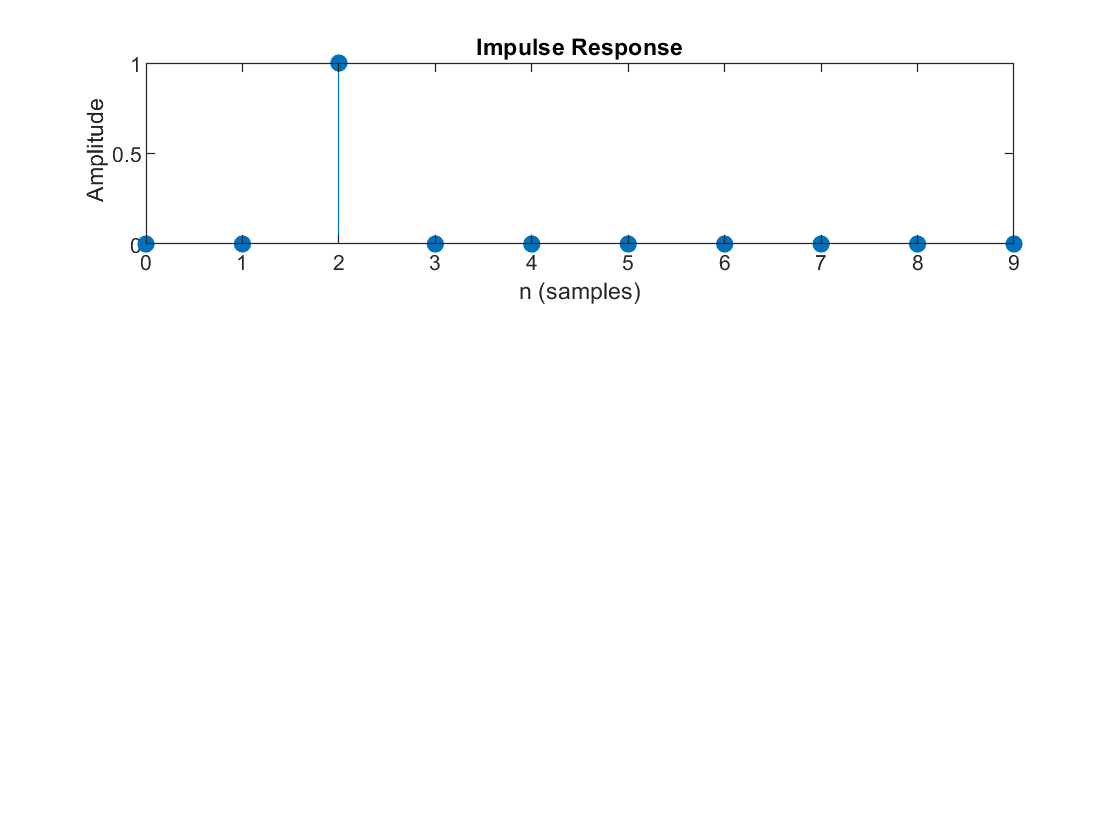

impz(Numerator,Denumerator,10)%we can se in this plot that the unit impulse gets delayed by 2

So if we have a delay of two samples, where do our zeros lie on the plot?

We have a Pole at 0, do we have a double pole? i think so otherwise we wouldn't have rational functions, right?

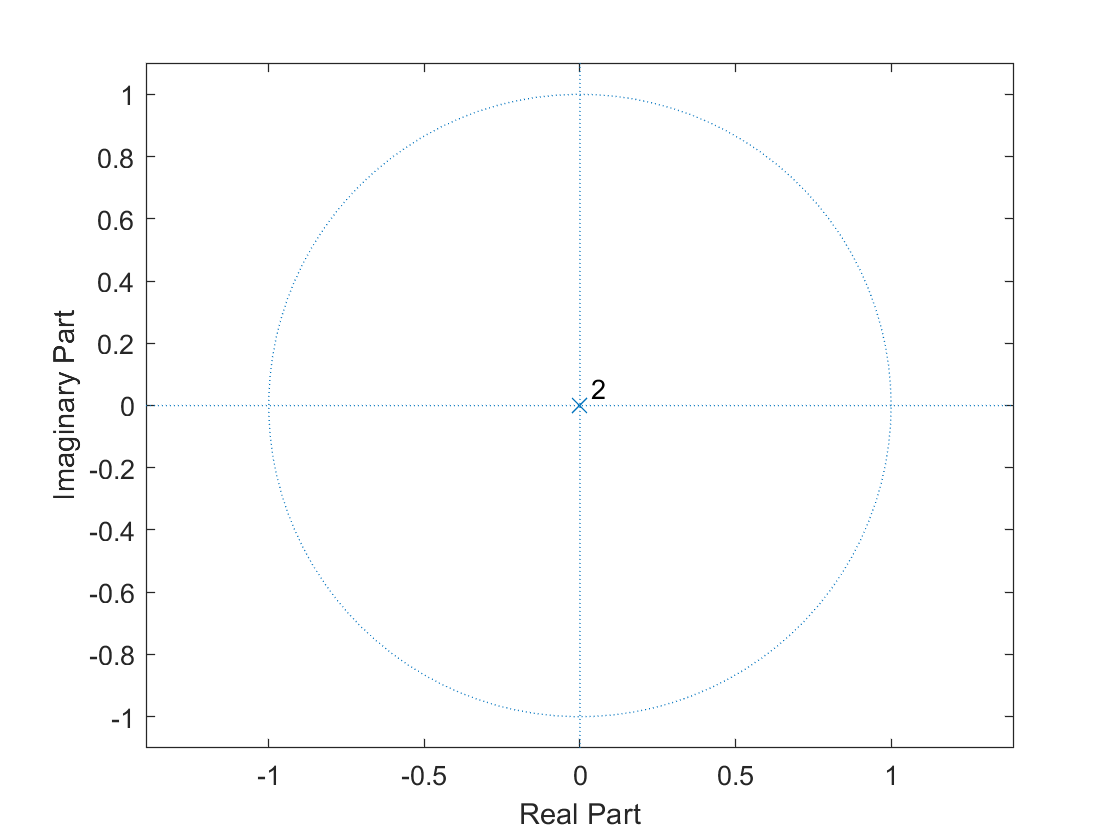

zplane(Numerator,Denumerator)%why don't we have any zeros?

## Frequency Response

- def. Describes the Systembehaviour as a function of the **frequency of the Input Signal !!!!**

- can directly be measured by applying sinusoidals at the different frequencies and looking at output, **frequency sweep, **the observe Output

- alternatively just **transform impulse response**

                                        

- consists of an **amplitude response and a phaseresponse**

                                        

- **amplituderesponse **describes how much a signal with a certain frequency is dampened or amplified

                                    

- **phaseresponse **describes how much a signal with a certain frequency is delayed, (das delta gehts da um die frequenzkomponente?)

                        

- **groupdelay **defined as the timedelay all frequency components undergo when travelling through de system. it is emasured in **Ts**

                                           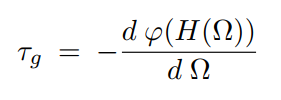

function y_1 = myConv(x,h) 
    for n=1:2*length(x)-1
        x(numel(h))=0
        y_1(n)=sum(x.*h)
        h=circshift( [h zeros(1,1 )], 1  )
    end   
end